# AuE-6600 | Dynamic Performance of Vehicles

## Homework 7

### Problem 1

**Part A:**

A vehicle with a 9 ft wheelbase and 4.5 ft front and rear tracks is placed on scales. The measured wheel loads are:

- LF = 850 lb

- RF = 825 lb

- LR = 725 lb

- RR = 750 lb

A. Find the x and y locations of the car’s center of gravity, measured from the rear axle and left side of the vehicle, respectively.

B. What is the diagonal weight, D, for this vehicle?

### Solution 1

A. Find the x and y locations of the car’s center of gravity, measured from the rear axle and left side of the vehicle, respectively.

% Given data
l = 9; % ft
l = l/3.281; % m
t = 4.5; %ft
t = t/3.281; % m
LF = 850; % lb
LF = LF*4.448; % N
RF = 825; % lb
RF = RF*4.448; % N
LR = 725; % lb
LR = LR*4.448; % N
RR = 750; % lb
RR = RR*4.448; % N
% Fing CG coordinates
W = LF+RF+LR+RR;
X_CG = (l/W)*(LF+RF);
Y_CG = (t/W)*(RF+RR);
fprintf("The location of the car's center of gravity is: X_CG = %.4f m, Y_CG = %.4f m", X_CG, Y_CG)

The location of the car's center of gravity is: X_CG = 1.4586 m, Y_CG = 0.6858 m

B. What is the diagonal weight, D, for this vehicle?

D = (LF+RR)-(RF+LR);
fprintf("The diagonal weight for this vehicle is: D = %.4f N", D)

The diagonal weight for this vehicle is: D = 222.4000 N

### Problem 2

A 20 kN car with 1.6 m front and rear tracks has CG at the center of the trackwidth.

A. If the car can corner at 0.9g, how high must the CG be to cause untripped rollover?

B. What is the total load transfer if the CG height is half of the rollover height?

C. The suspension springs in the rear are 25% stiffer than the ones in the front. Where (front or rear) would you add an anti-roll and what torsional stiffness would the roll bar need to provide for the lateral load transfer to be evenly distributed between front and rear?

D. Now, if the vehicle has 3m wheelbase, 58% front weight, 52% left weight and 25 N of diagonal weight; then calculate the static wheel loads.

### Solution 2

A. If the car can corner at 0.9g, how high must the CG be to cause untripped rollover?

% Given data
W = 20*1e3; % N
t = 1.6; % m
A_y = 0.9; % g's
% Calculate CG height
h_c = t/(2*A_y);
fprintf("If the car can corner at 0.9g, the CG must be %.4f m high to cause untripped rollover", h_c)

If the car can corner at 0.9g, the CG must be 0.8889 m high to cause untripped rollover

B. What is the total load transfer if the CG height is half of the rollover height?

h_half = h_c/2;
w_y = (W*A_y*h_half)/t;
fprintf("If the CG height is half of the rollover height, the the total load transfer is %.4f N", w_y)

If the CG height is half of the rollover height, the the total load transfer is 5000.0000 N

C. The suspension springs in the rear are 25% stiffer than the ones in the front. Where (front or rear) would you add an anti-roll and what torsional stiffness would the roll bar need to provide for the lateral load transfer to be evenly distributed between front and rear?

K_R_F = 1.25; % K_phi_R is 25% more than K_phi_F
% K_phi_R == K_phi_F ==> K_phi_R = 1/2*K_F*t^2 + K_phi_aux
K_phi_aux = (0.5*K_R_F*t^2) - (0.5*1*t^2);
fprintf("The anti-roll bar should be added in front to compensate for excess stiffness in rear suspension springs\n" + ...
        "The anti-roll bar should have a torsional stiffness of %.4f times stiffness of front suspension springs", K_phi_aux)

The anti-roll bar should be added in front to compensate for excess stiffness in rear suspension springs
The anti-roll bar should have a torsional stiffness of 0.3200 times stiffness of front suspension springs

D. Now, if the vehicle has 3m wheelbase, 58% front weight, 52% left weight and 25 N of diagonal weight; then calculate the static wheel loads.

% Given data
l = 3; % m
t = 1.6; % m
W = 20*1e3; % N
D = 25; % N
X_CG = 0.58*l;
Y_CG = (1-0.52)*t;

Solve system of equations:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & 1 & 0 & 0\\
0 & 1 & 0 & 1\\
1 & -1 & -1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F_{z_{\textrm{LF}} } \\
F_{z_{\textrm{RF}} } \\
F_{z_{\textrm{LR}} } \\
F_{z_{\textrm{RR}} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
W\\
\frac{W*X_{\textrm{CG}} }{l}\\
\frac{W*Y_{\textrm{CG}} }{t}\\
D
\end{array}\right\rbrack$$


A = [1  1  1  1;
     1  1  0  0;
     0  1  0  1;
     1 -1 -1  1];
B = [W;
     (W*X_CG)/l;
     (W*Y_CG)/t;
     D];
Fz = linsolve(A,B);
fprintf("Static wheel loads are:\n" + ...
        "Left-Front:\t%.4f N\n" + ...
        "Right-Front:\t%.4f N\n" + ...
        "Left-Rear:\t%.4f N\n" + ...
        "Right-Rear:\t%.4f N", Fz(1), Fz(2), Fz(3), Fz(4))

Static wheel loads are:
Left-Front:	6006.2500 N
Right-Front:	5593.7500 N
Left-Rear:	4393.7500 N
Right-Rear:	4006.2500 N

### Problem 3

Let’s revisit the simulation problem with load transfer (and the nonlinear tire model) from the last homework assignment. Now, we want to perform the simulation while accounting for a more sophisticated model of the roll dynamics in load transfer. The maneuvers shall remain the same from the previous homework assignment. Provide the relevant plots for maneuver 1 (step input) and maneuver 2 (fishhook maneuver) for the following conditions:

A. Steady state roll: at each point in time, calculate the steady-state roll angle (assuming that there are no transients) and the resulting load transfer including roll (see lecture notes)

B. Dynamic roll: introduce 2 new states for roll angle and roll velocity to augment the state-space system and utilize the second order roll dynamics as discussed in class to calculate these states at each point in time. Incorporate the actual (dynamic) roll angle with transients in your load transfer calculations.

C. Compare your solutions from Parts A and B.

Additional Parameters:

- Front roll center height: 0.33 ft

- Rear roll center height: 0.5 ft

- Total roll stiffness: 50000 Nm/rad

- Roll damping: 3500 Nm-s/rad

- Roll plane inertia: 700 kg-m^2

- Roll Stiffness distribution: 58% front

% Vehicle parameters
m = 1637; % kg
m_sprung = 1*m; % kg
Iz = 3326; % kg-m^2
l = 2.736; % m
w = 1.7; % m
m_a = 0.4*l;
m_b = l-m_a;
C_alpha_F = 1500; % N/deg
C_alpha_F = C_alpha_F*(180/pi); % N/rad
C_alpha_R = 1146; % N/deg
C_alpha_R = C_alpha_R*(180/pi); % N/rad
SR = 15;
h_c = 2.4; % ft
h_c = h_c/3.281; % m
% Additional vehicle parameters
h_f = 0.33; % ft
h_f = h_f/3.281; % m
h_r = 0.5; % ft
h_r = h_r/3.281; % m
h_cr = h_c - (h_f + (h_r-h_f)/(l)*m_a);
k_SR = 50000; % Nm/rad
B_R = 3500; % Nm-s/rad
Ix = 700 + m_sprung*h_cr^2; % kg-m^2
r_a = 0.58;
r_b = 1-r_a;
% Static load
S_fl = 0.5*0.6*m*9.81;
S_fr = 0.5*0.6*m*9.81;
S_rl = 0.5*0.4*m*9.81;
S_rr = 0.5*0.4*m*9.81;

% Maneuver description
% Step maneuver
v_step = 74; % mph
v_step = v_step/2.237; % m/s
u_step = [ones(1,7000)*0 ones(1,60000)*(deg2rad(45)/SR) ones(1,13000)*0];
% Fishhook manuever
v_fishhook = 50; % mph
v_fishhook = v_fishhook/2.237; % m/s
u_fishhook = [ones(1,5000)*0 deg2rad(0:(14.5/1000):270)/SR ones(1,4000)*deg2rad(270)/SR ones(1,7379)*0];

A. Steady State Roll

1. Step Maneuver

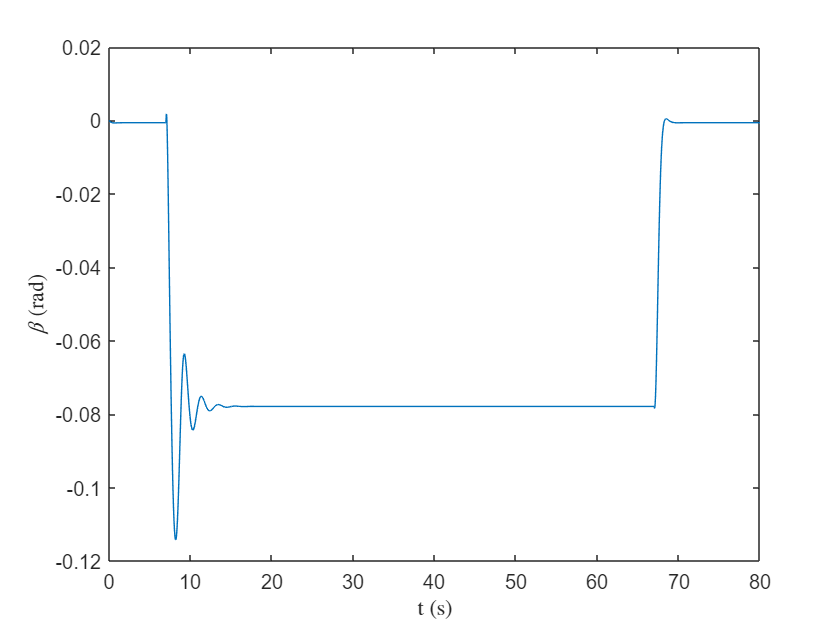

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
% Simulation at each millisecond
for t=1:80000
    a_y = v_step*(B_dot+X(2,t));
    Phi(t) = (m_sprung*a_y*h_cr)/(k_SR-(m_sprung*9.81*h_cr));
    dW_f = (r_a*k_SR*Phi(t))/w + m_sprung*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m_sprung*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_step(t) - (X(2,t)*m_a)/v_step - X(1,t);
    alpha_r = (X(2,t)*m_b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:80000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

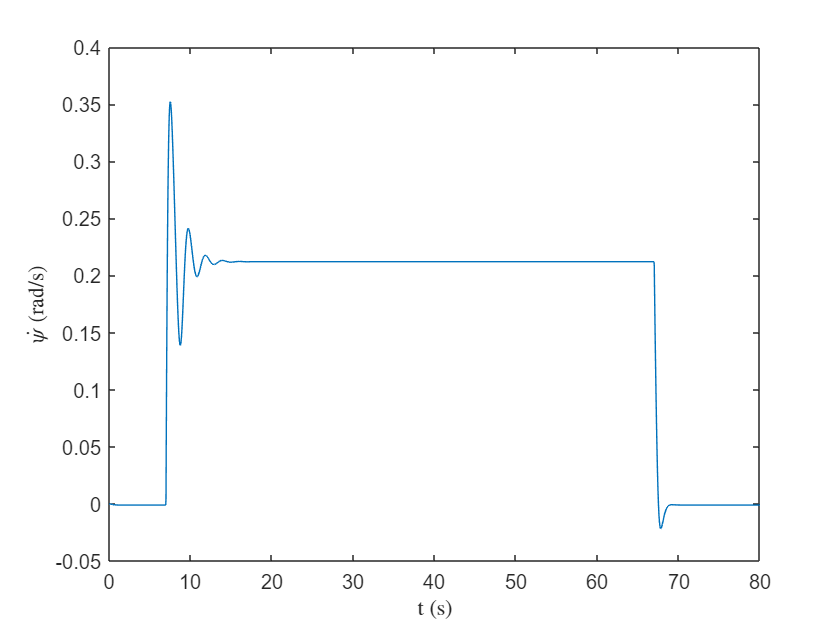

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

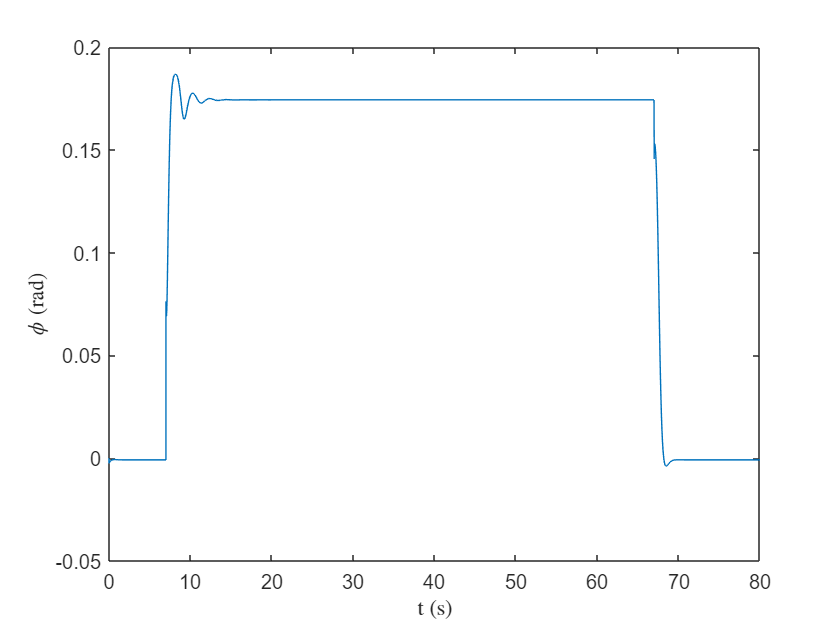

plot(t(1:end-1)/1000,Phi)
xlabel("t (s)",'interpreter','latex')
ylabel("$\phi$ (rad)",'interpreter','latex')

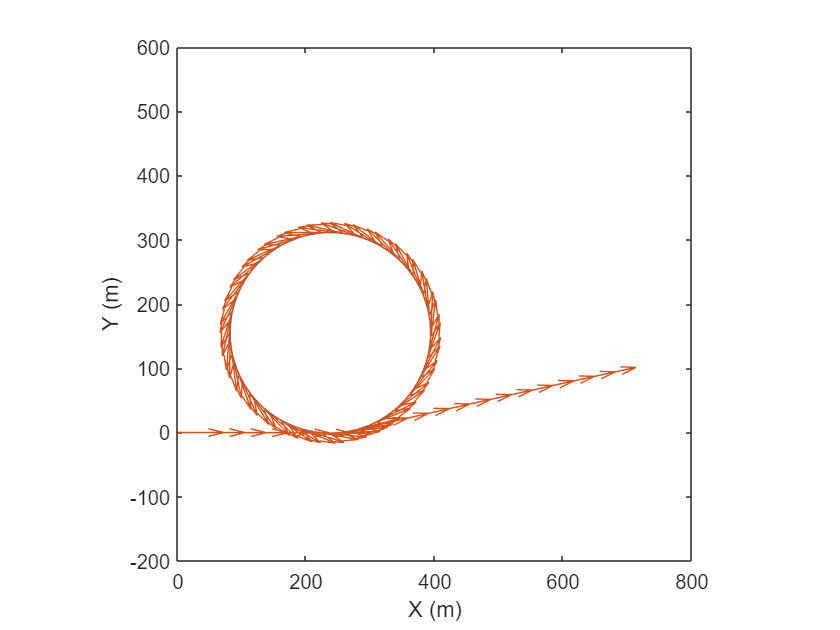

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,800])
ylim([-200,600])
pbaspect([1 1 1])

2. Fishhook Maneuver

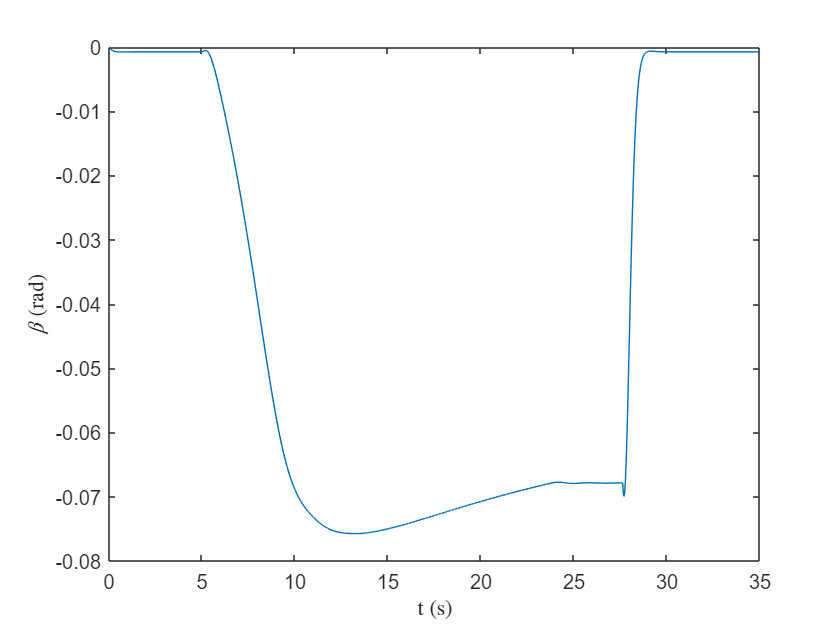

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
% Simulation at each millisecond
for t=1:35000
    a_y = v_fishhook*(B_dot+X(2,t));
    Phi(t) = (m_sprung*a_y*h_cr)/(k_SR-(m_sprung*9.81*h_cr));
    dW_f = (r_a*k_SR*Phi(t))/w + m_sprung*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m_sprung*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_fishhook(t) - (X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_r = (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

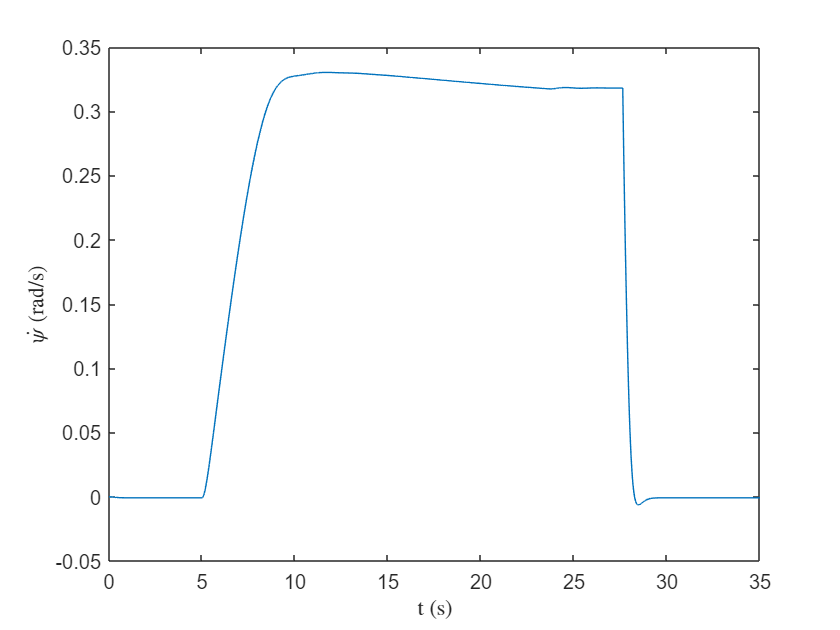

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

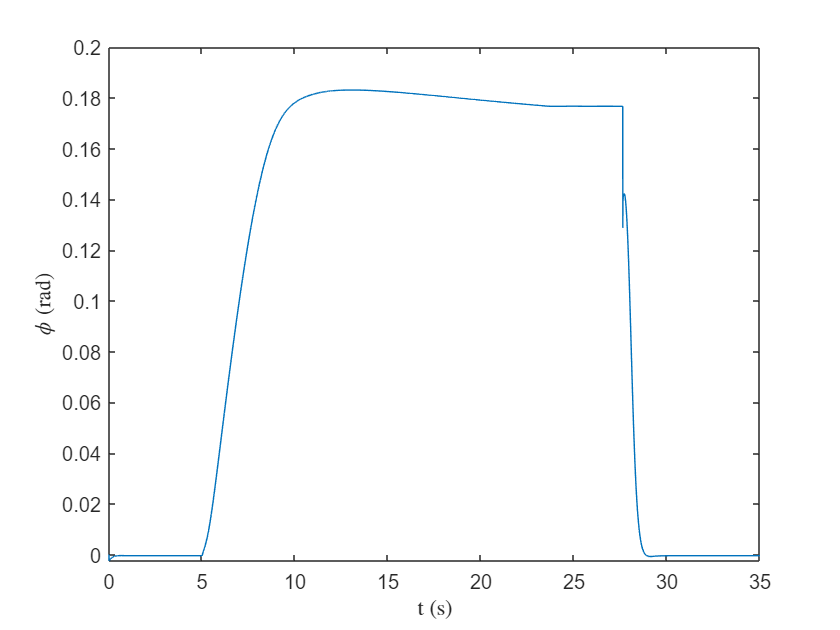

plot(t(1:end-1)/1000,Phi)
xlabel("t (s)",'interpreter','latex')
ylabel("$\phi$ (rad)",'interpreter','latex')

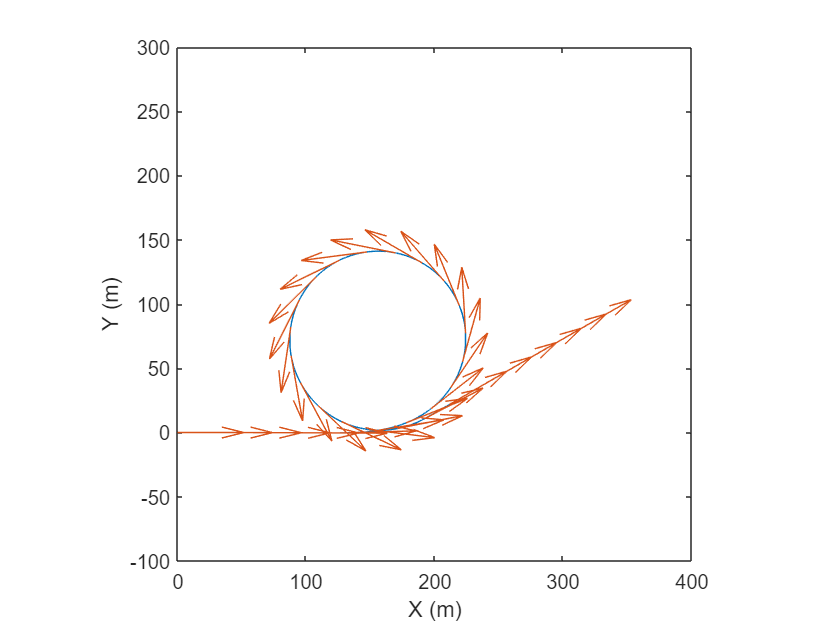

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,400])
ylim([-100,300])
pbaspect([1 1 1])

B. Dynamic Roll

1. Step Maneuver

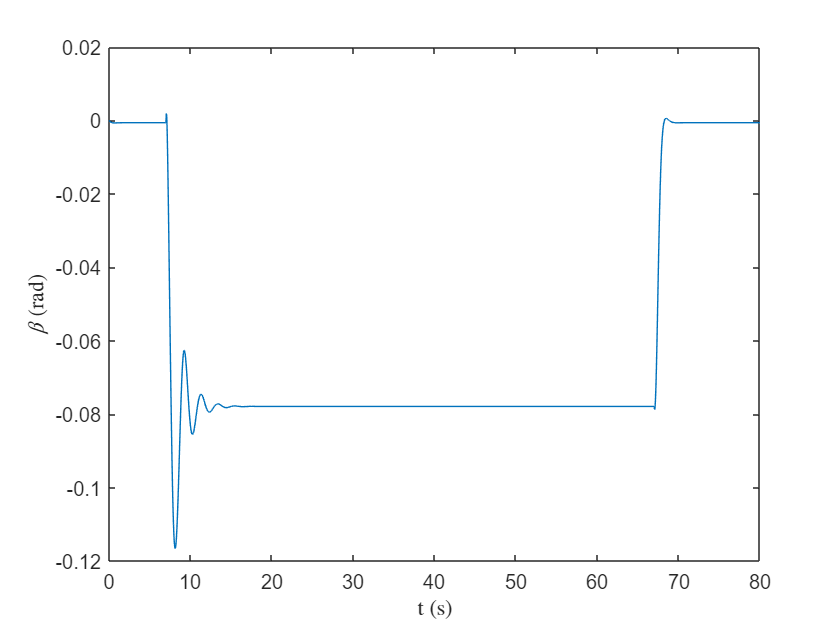

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_dot_dot = [];
Phi_dot_dot = 0;
% Simulation at each millisecond
for t=1:80000
    a_y = v_step*(B_dot+X(2,t));
    Phi_dot_dot(t+1) = (1/Ix)*(m_sprung*a_y*h_cr + m_sprung*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_dot_dot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m_sprung*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m_sprung*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_step(t) - (X(2,t)*m_a)/v_step - X(1,t);
    alpha_r = (X(2,t)*m_b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:80000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

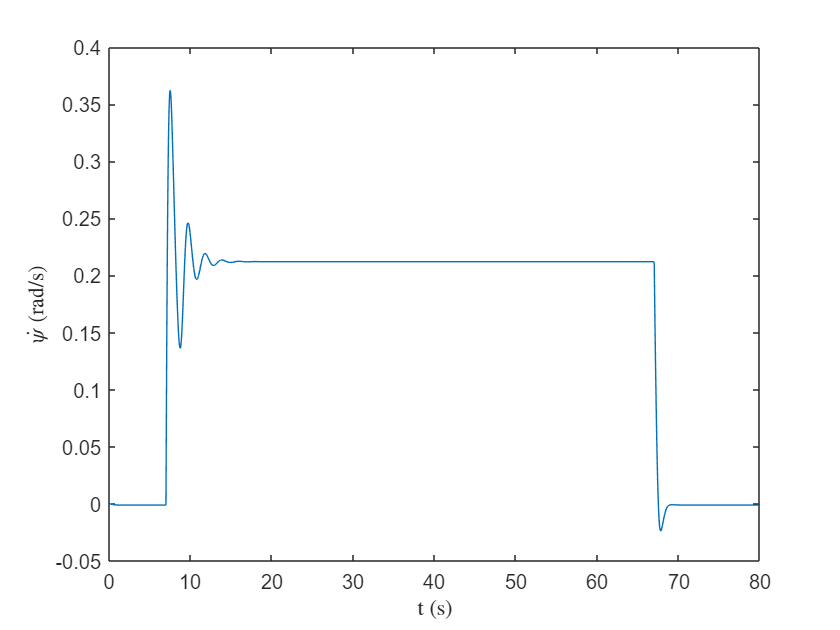

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

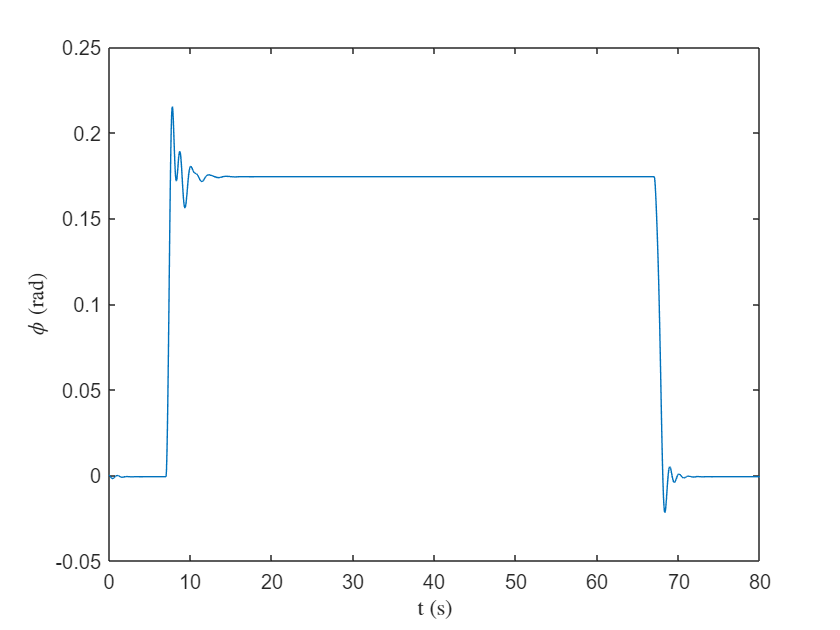

plot(t/1000,Phi)
xlabel("t (s)",'interpreter','latex')
ylabel("$\phi$ (rad)",'interpreter','latex')

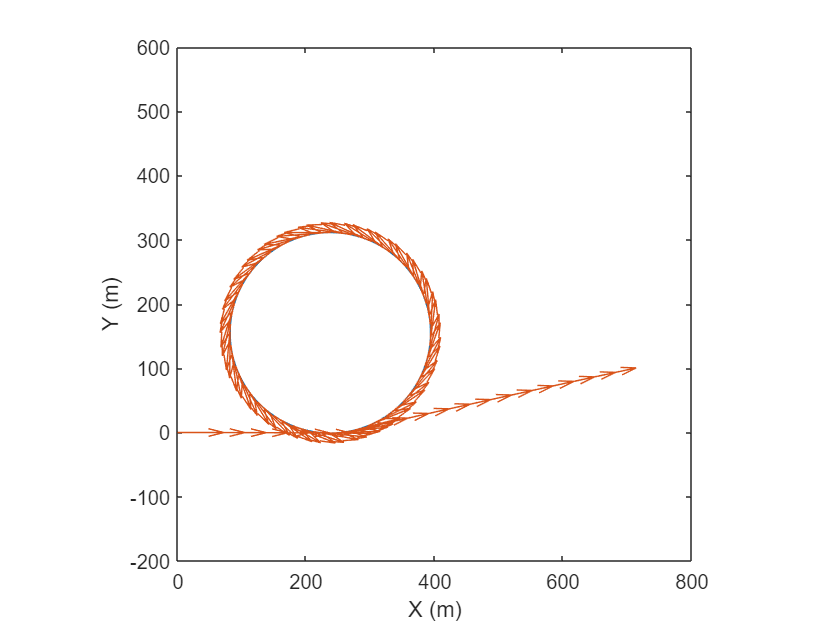

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,800])
ylim([-200,600])
pbaspect([1 1 1])

2. Fishhook Maneuver

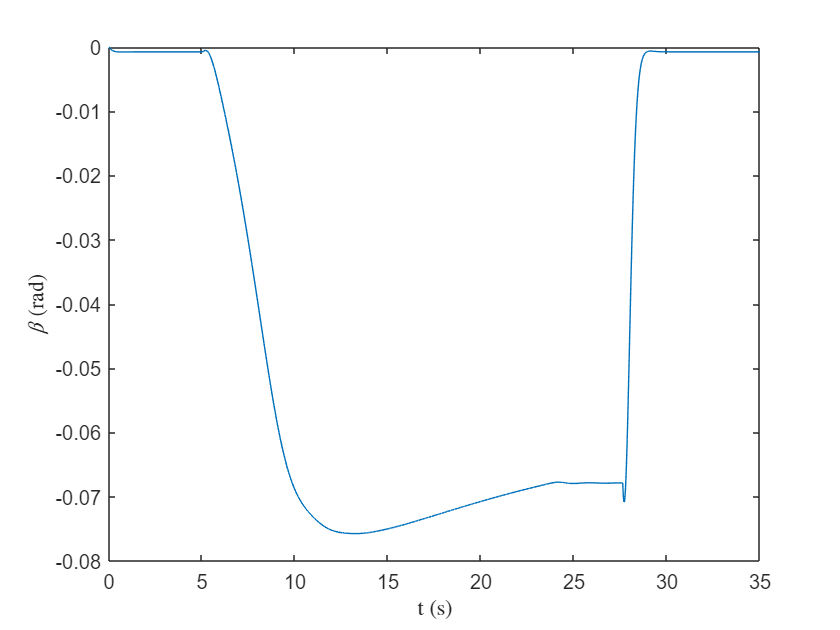

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
Phi = [];
Phi(1) = 0;
Phi_dot = [];
Phi_dot(1) = 0;
Phi_dot_dot = [];
Phi_dot_dot = 0;
% Simulation at each millisecond
for t=1:35000
    a_y = v_fishhook*(B_dot+X(2,t));
    Phi_dot_dot(t+1) = (1/Ix)*(m_sprung*a_y*h_cr + m_sprung*9.81*h_cr*Phi(t) - B_R*Phi_dot(t) - k_SR*Phi(t));
    Phi_dot(t+1) = Phi_dot(t) + Phi_dot_dot(t)*dt;
    Phi(t+1) = Phi(t) + Phi_dot(t)*dt;
    dW_f = (r_a*k_SR*Phi(t))/w + m_sprung*a_y*(m_b/l)*(h_f/w);
    dW_r = (r_b*k_SR*Phi(t))/w + m_sprung*a_y*(m_a/l)*(h_r/w);
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_fishhook(t) - (X(2,t)*m_a)/v_fishhook - X(1,t);
    alpha_r = (X(2,t)*m_b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*m_a-Fy_r*m_b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

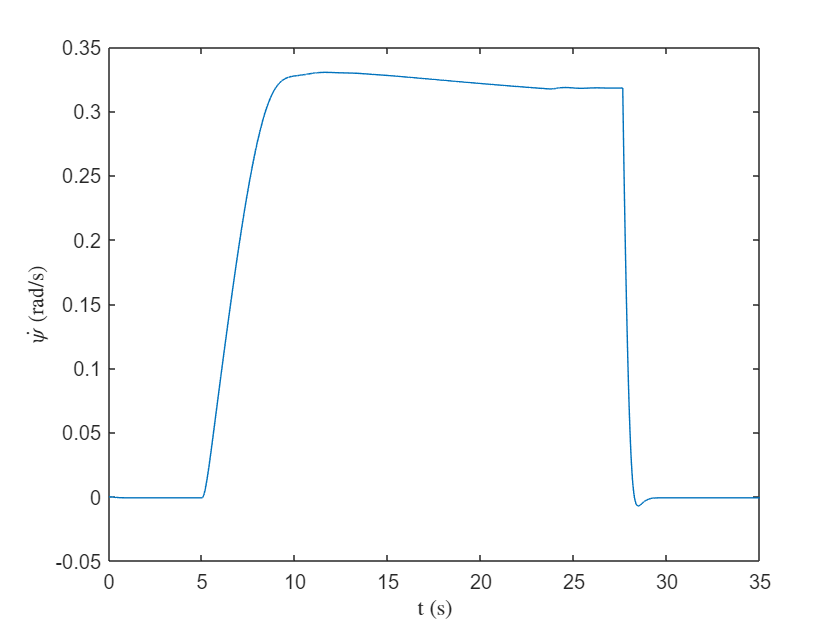

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

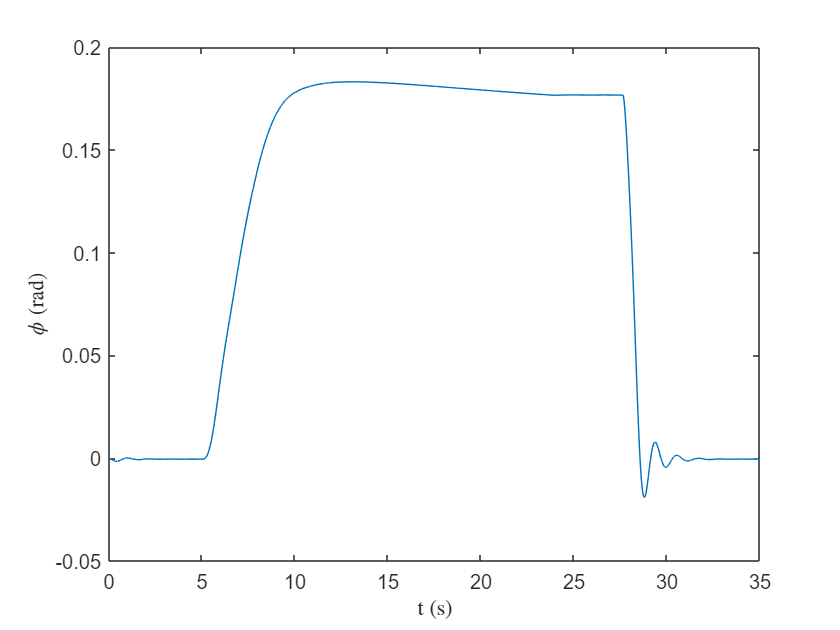

plot(t/1000,Phi)
xlabel("t (s)",'interpreter','latex')
ylabel("$\phi$ (rad)",'interpreter','latex')

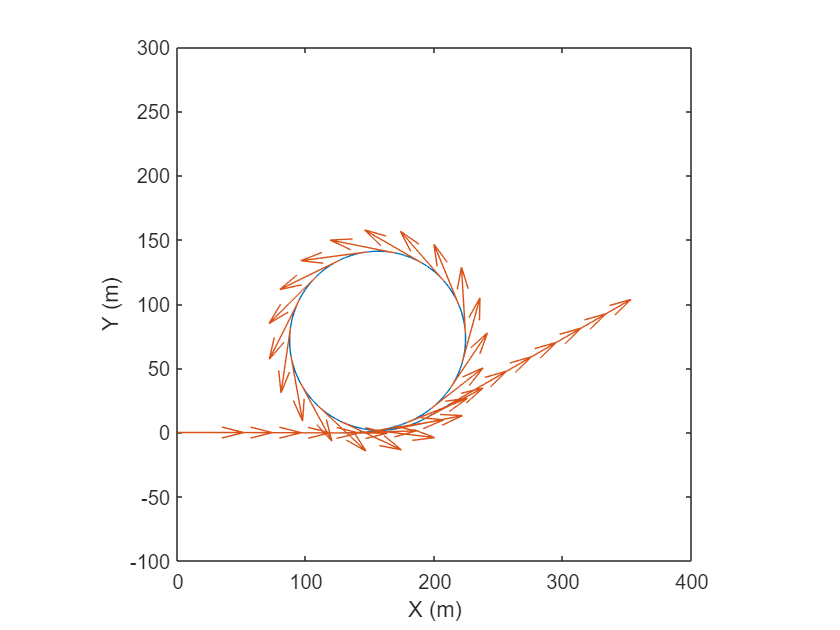

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,400])
ylim([-100,300])
pbaspect([1 1 1])